# FIR low pass Filter Design and Implementation

## Design Filter

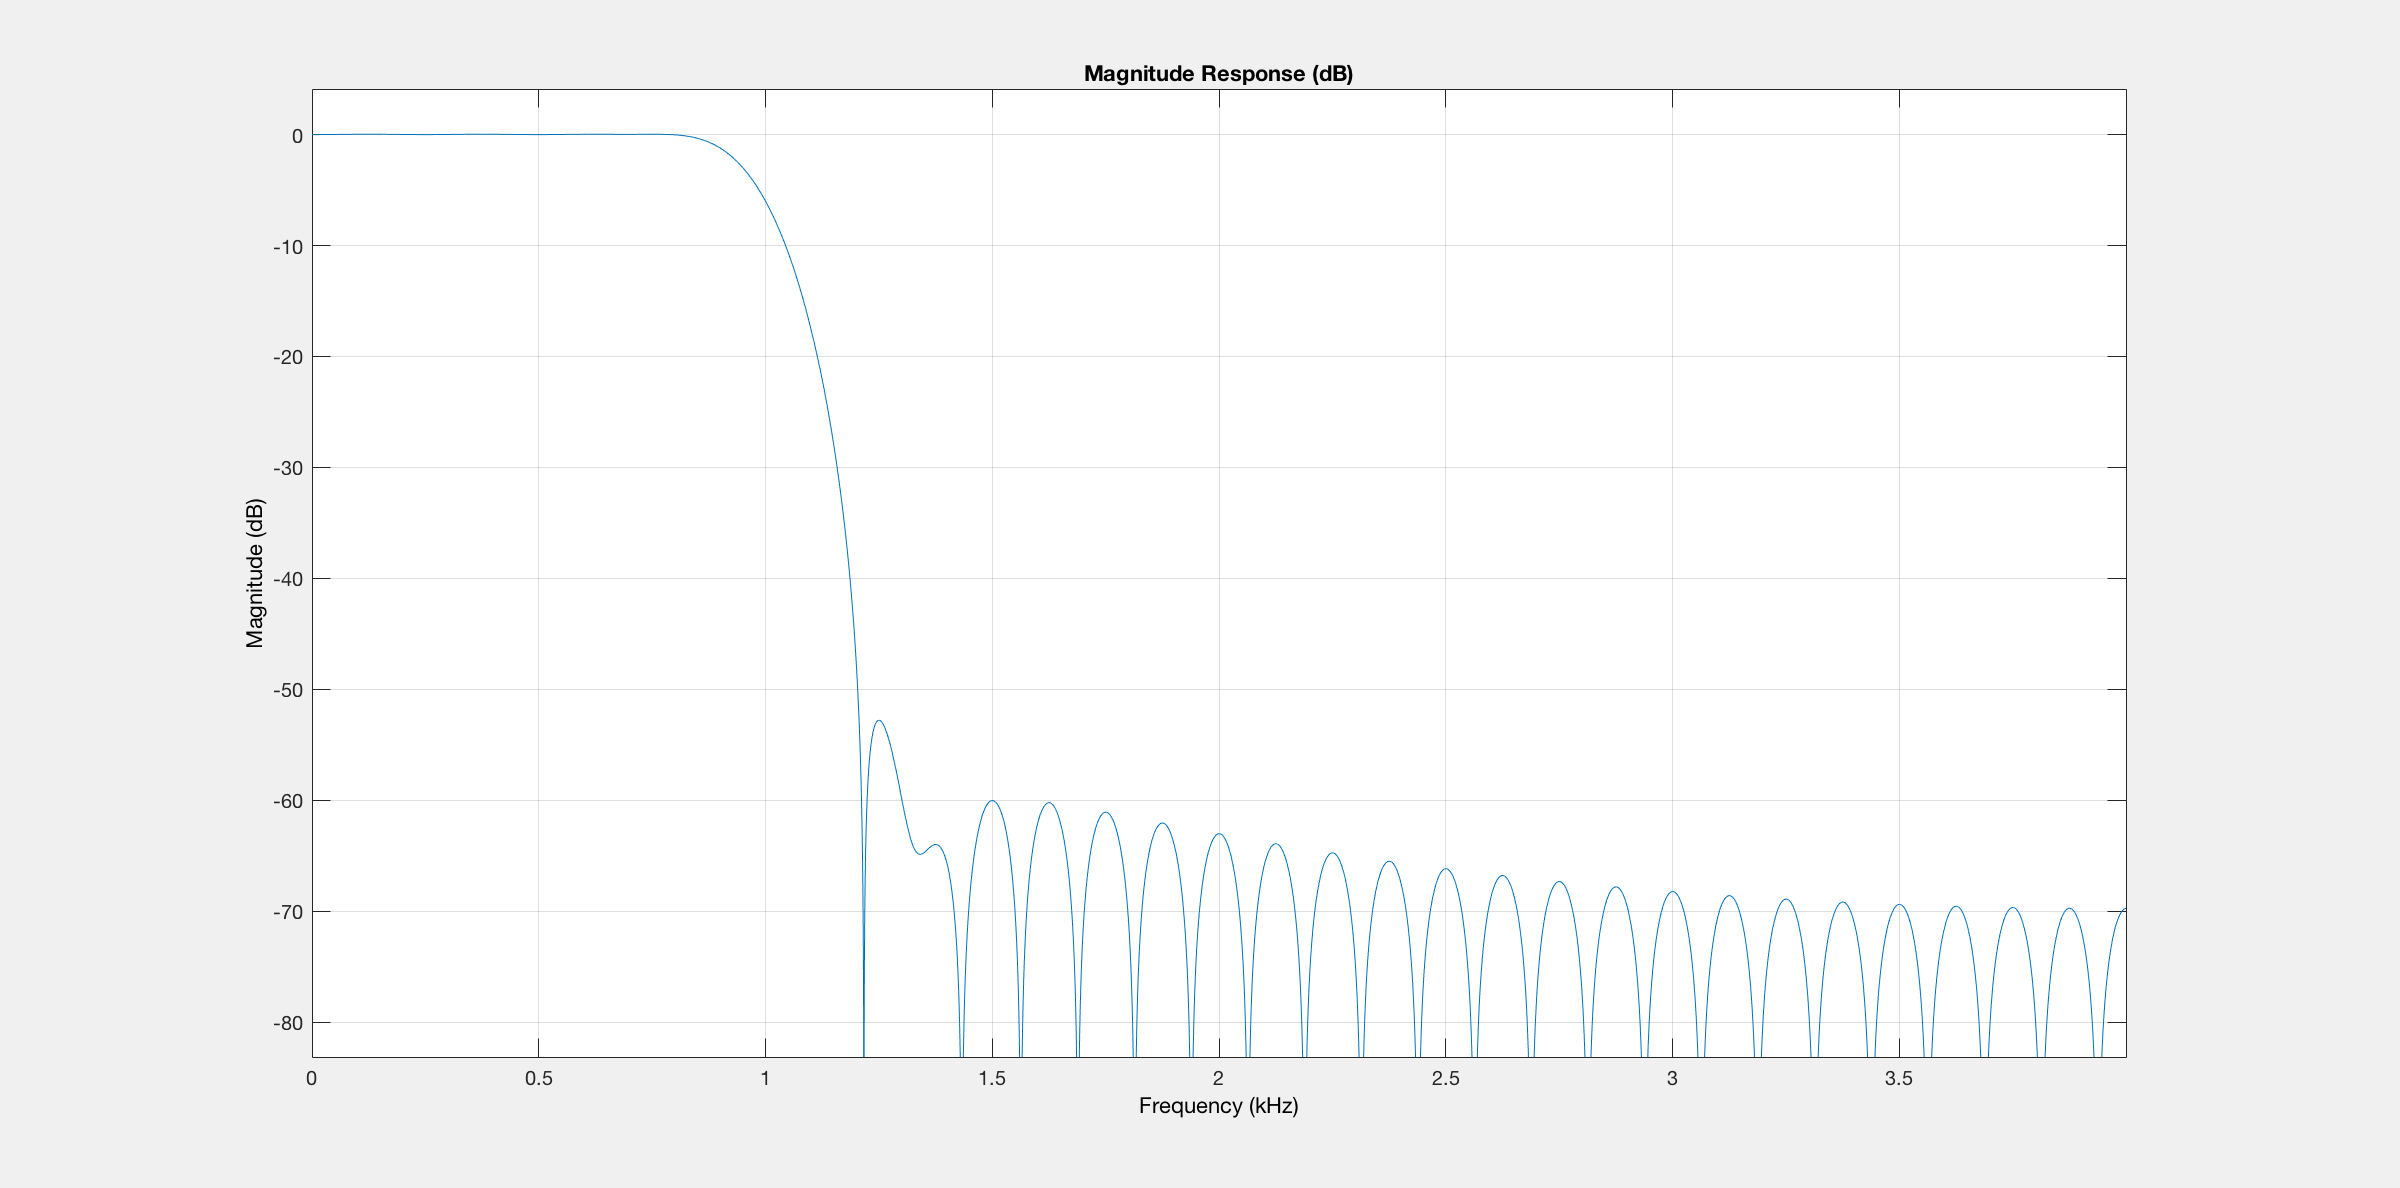

Fstop = 1000;
Fs = 8000;
Ntaps = 65;


order = Ntaps - 1;
Wn = Fstop/Fs*2;
coeff = fir1(order,Wn);

% h=fvtool(coeff,'Fs',Fs);

## Struktur und Skalierung

% Scale so that sum of absolute coefficients is smaller than 1
coeff = coeff ./ sum(abs(coeff));
% Scale to Q15 format
coeffQ15 = int16(floor(coeff .* 32767));
% Print ready to paste to header file
coeffQ15string = sprintf('%.0f,' , coeffQ15);
coeffQ15string = coeffQ15string(1:end-1);% strip final comma
outHeader = sprintf('//FIR-LP fs=%d fc=%d NTAPS=%d\n%s\n%s\n%s',Fs,Fstop,Ntaps,'fractional coefficients[NTAPS] __attribute__ ((space(xmemory),far)) = {',coeffQ15string,'};');
disp(outHeader)

//FIR-LP fs=8000 fc=1000 NTAPS=65
fractional coefficients[NTAPS] __attribute__ ((space(xmemory),far)) = {
-1,-12,-19,-16,0,21,37,32,-1,-48,-81,-69,0,94,156,128,-1,-173,-282,-230,0,304,497,408,-1,-566,-962,-837,0,1444,3099,4412,4911,4412,3099,1444,0,-837,-962,-566,-1,408,497,304,0,-230,-282,-173,-1,128,156,94,0,-69,-81,-48,-1,32,37,21,0,-16,-19,-12,-1
};
